读取音频：

clear;close all
% 读取数据和采样率
[x,fs] = audioread('bluesky1.wav');
% 读取采样位数
info = audioinfo('bluesky1.wav');
%定点化
x=x.*32768;
plot(x);title('时域图');

分析滤波器

h=[0.01218354,-0.009012882, -0.02881839, -0.04743239, -0.04584568,-0.008692503,0.06446265, 0.1544655, 0.2289794, 0.257883, 0.2289794, 0.1544655, 0.06446265, -0.008692503, -0.04584568,-0.04743239, -0.02881839, -0.009012882, 0.01218354];
[H,w]=freqz(h,1);
w=w./(2*pi).*fs;
plot(w, abs(H));
xlabel('频率 (Hz)');
ylabel('幅度');
title('频谱图');
%计算最大值
[max_H,max_index]=max(abs(H));
cutoff_H=max_H./sqrt(2);
f_h_index=find(abs(H)>=cutoff_H,1,"last");
f_h=w(f_h_index);

滤波前

clear;close all
% 读取数据和采样率
[x,fs] = audioread('bluesky1.wav');
% 读取采样位数
info = audioinfo('bluesky1.wav');
x=x.*32768;
%时间变换
t=[0:(info.Duration*fs)-1]./fs;
t=t';
%时域图绘制
plot(t,x);
xlabel('时间 (s)');
ylabel('幅度');
title('滤波前时域图');
%DFT
[H,w]=freqz(x,1);
%频率变换
w=w./(2*pi).*fs;
%频谱图绘制
plot(w, abs(H));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波前频谱图');
% 设置语谱图参数
window = hamming(256); % 窗口函数
noverlap = 128; % 重叠区域
nfft = 256; % FFT 点数

% 生成语谱图
figure;
spectrogram(x, window, noverlap, nfft, fs, 'yaxis');
title('滤波前语谱图');

前五帧

%设置帧长
N=180;
%提取前五帧数据
x1=x(1:N);
x2=x(N+1:2*N);
x3=x(2*N+1:3*N);
x4=x(3*N+1:4*N);
x5=x(4*N+1:5*N);
%DFT
[H1,w1]=freqz(x1,1);
[H2,w2]=freqz(x2,1);
[H3,w3]=freqz(x3,1);
[H4,w4]=freqz(x4,1);
[H5,w5]=freqz(x5,1);
%频率变换
w1=w1./(2*pi).*fs;
w2=w2./(2*pi).*fs;
w3=w3./(2*pi).*fs;
w4=w4./(2*pi).*fs;
w5=w5./(2*pi).*fs;
%频谱图绘制
plot(w1, abs(H1));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波前第1帧频谱图');
plot(w2, abs(H2));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波前第2帧频谱图');
plot(w3, abs(H3));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波前第3帧频谱图');
plot(w4, abs(H4));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波前第4帧频谱图');
plot(w5, abs(H5));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波前第5帧频谱图');

滤波后

clear;close all
% 读取数据和采样率
[x,fs] = audioread('outsp1.wav');
% 读取采样位数
info = audioinfo('outsp1.wav');
x=x.*32768;
%时间变换
t=[0:(info.Duration*fs)-1]./fs;
t=t';
%时域图绘制
plot(t,x);
xlabel('时间 (s)');
ylabel('幅度');
title('滤波后时域图');
%DFT
[H,w]=freqz(x,1);
%频率变换
w=w./(2*pi).*fs;
%频谱图绘制
plot(w, abs(H));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波后频谱图');
% 设置语谱图参数
window = hamming(256); % 窗口函数
noverlap = 128; % 重叠区域
nfft = 256; % FFT 点数

% 生成语谱图
figure;
spectrogram(x, window, noverlap, nfft, fs, 'yaxis');
title('滤波后语谱图');

前五帧

%设置帧长
N=180;
%提取前五帧数据
x1=x(1:N);
x2=x(N+1:2*N);
x3=x(2*N+1:3*N);
x4=x(3*N+1:4*N);
x5=x(4*N+1:5*N);
%DFT
[H1,w1]=freqz(x1,1);
[H2,w2]=freqz(x2,1);
[H3,w3]=freqz(x3,1);
[H4,w4]=freqz(x4,1);
[H5,w5]=freqz(x5,1);
%频率变换
w1=w1./(2*pi).*fs;
w2=w2./(2*pi).*fs;
w3=w3./(2*pi).*fs;
w4=w4./(2*pi).*fs;
w5=w5./(2*pi).*fs;
%频谱图绘制
plot(w1, abs(H1));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波后第1帧频谱图');
plot(w2, abs(H2));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波后第2帧频谱图');
plot(w3, abs(H3));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波后第3帧频谱图');
plot(w4, abs(H4));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波后第4帧频谱图');
plot(w5, abs(H5));
xlabel('频率 (Hz)');
ylabel('幅度');
title('滤波后第5帧频谱图');

噪声生成

clear;close all
% 读取数据和采样率
[x,fs] = audioread('bluesky1.wav');
% 读取采样位数
info = audioinfo('bluesky1.wav');
%生成噪声
noise_low_f=100;
noise_low_a=0.2;
noise_high_f=2000;
noise_high_a=0.2;
t=[0:length(x)-1]./fs;
noise_low=noise_low_a.*sin(2*pi*noise_low_f*t);
noise_high=noise_high_a.*sin(2*pi*noise_high_f*t);
%叠加噪声进行回写
x_1=x+noise_low'+noise_high';
audiowrite('bluesky2.wav',x_1,fs);

clear;close all
% 读取数据和采样率
[x,fs] = audioread('bluesky1.wav');
% 读取采样位数
info = audioinfo('bluesky1.wav');
x=x.*32768;
%时间变换
t=[0:(info.Duration*fs)-1]./fs;
t=t';
%时域图绘制
plot(t,x);
xlabel('时间 (s)');
ylabel('幅度');
title('加噪声前时域图');
%DFT
[H,w]=freqz(x,1);
%频率变换
w=w./(2*pi).*fs;
%频谱图绘制
plot(w, abs(H));
xlabel('频率 (Hz)');
ylabel('幅度');
title('加噪声前频谱图');
% 设置语谱图参数
window = hamming(256); % 窗口函数
noverlap = 128; % 重叠区域
nfft = 256; % FFT 点数

% 生成语谱图
figure;
spectrogram(x, window, noverlap, nfft, fs, 'yaxis');
title('加噪声前语谱图');

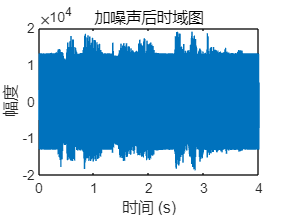

clear;close all
% 读取数据和采样率
[x,fs] = audioread('bluesky2.wav');
% 读取采样位数
info = audioinfo('bluesky2.wav');
x=x.*32768;
%时间变换
t=[0:(info.Duration*fs)-1]./fs;
t=t';
%时域图绘制
plot(t,x);
xlabel('时间 (s)');
ylabel('幅度');
title('加噪声后时域图');

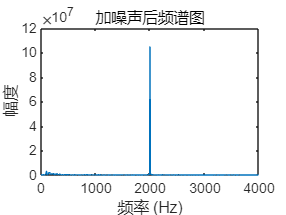

%DFT
[H,w]=freqz(x,1);
%频率变换
w=w./(2*pi).*fs;
%频谱图绘制
plot(w, abs(H));
xlabel('频率 (Hz)');
ylabel('幅度');
title('加噪声后频谱图');

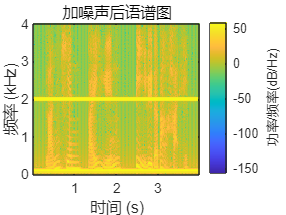

% 设置语谱图参数
window = hamming(256); % 窗口函数
noverlap = 128; % 重叠区域
nfft = 256; % FFT 点数

% 生成语谱图
figure;
spectrogram(x, window, noverlap, nfft, fs, 'yaxis');
title('加噪声后语谱图');

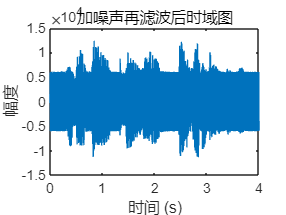

clear;close all
% 读取数据和采样率
[x,fs] = audioread('outsp2.wav');
% 读取采样位数
info = audioinfo('outsp2.wav');
x=x.*32768;
%时间变换
t=[0:(info.Duration*fs)-1]./fs;
t=t';
%时域图绘制
plot(t,x);
xlabel('时间 (s)');
ylabel('幅度');
title('加噪声再滤波后时域图');
xlim([0,4]);

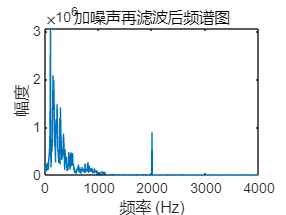

%DFT
[H,w]=freqz(x,1);
%频率变换
w=w./(2*pi).*fs;
%频谱图绘制
plot(w, abs(H));
xlabel('频率 (Hz)');
ylabel('幅度');
title('加噪声再滤波后频谱图');

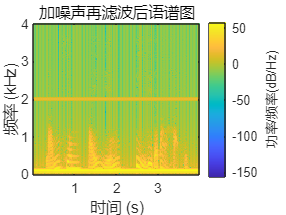

% 设置语谱图参数
window = hamming(256); % 窗口函数
noverlap = 128; % 重叠区域
nfft = 256; % FFT 点数

% 生成语谱图
figure;
spectrogram(x, window, noverlap, nfft, fs, 'yaxis');
title('加噪声再滤波后语谱图');